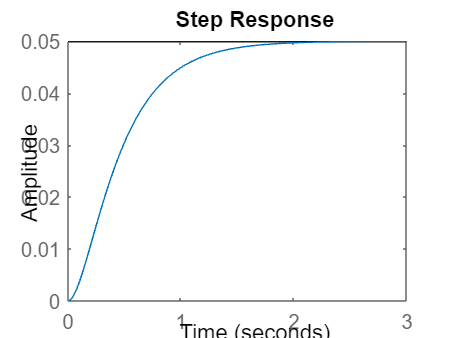

clear all
clc
M = 1;
b = 10;
k = 20;
F = 1;
num = [1];
den = [1 10 20];
plant = tf(num,den);
step(plant)

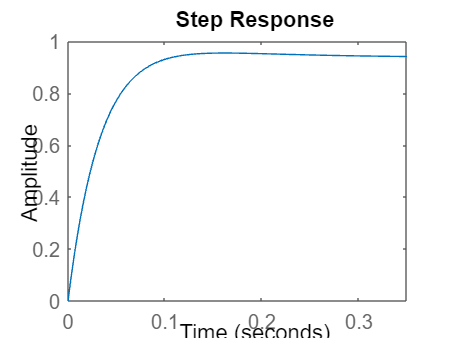


Kp = 300;
Kd = 30;
contr = tf([Kd Kp],1);
sys_cl = feedback(contr*plant,1);
step(sys_cl)

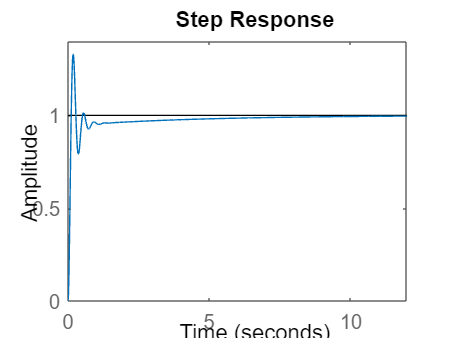


Ki = 70;
contr = tf([Kp Ki],[1,0]);
sys_cl = feedback(contr*plant,1);
step(sys_cl)

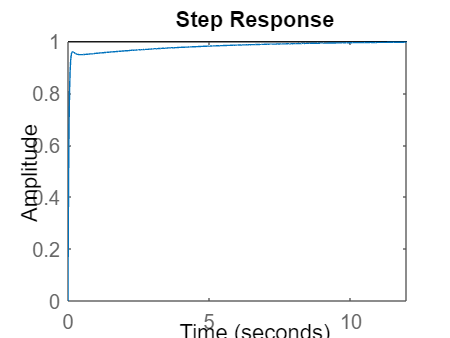


contr = tf([Kd Kp Ki],[1,0]);
sys_cl = feedback(contr*plant,1);
step(sys_cl)